# Experiment with Focus Stacking

Experiment with focus stacking using our cp (Computational Photography) classes. Eventually add object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering. We use its lens model to get realistic depth and occlusion rendering.

ieInit();
sceneLuminance = 200;
numRays = 128;
filmResolution = 256;

sceneChoice = "CornellBoxReference";
apertureDiameter = 6;% in mm

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "CornellBoxReference";
    sceneName = "CornellBoxReference";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.6.0mm.dat',...
    'apertureDiameter', apertureDiameter); % realistic camera needs .dat

Read 9 materials
Reading C4D geometry information.


## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('ar0132atSensorRGB'); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Let's Look at the Camera we've Created

cpCameraWindow is actually a mini-application, that lets you see the properties of your camera, and the scene you've chosen. You can use it to take photos in whatever modes your camera supports. It also allows to to set Advanced Processing, which tells cameras that support it to do additional processing like image registration and tonemapping, as needed, in their ISP, instead of the default combination of frames in the sensor.

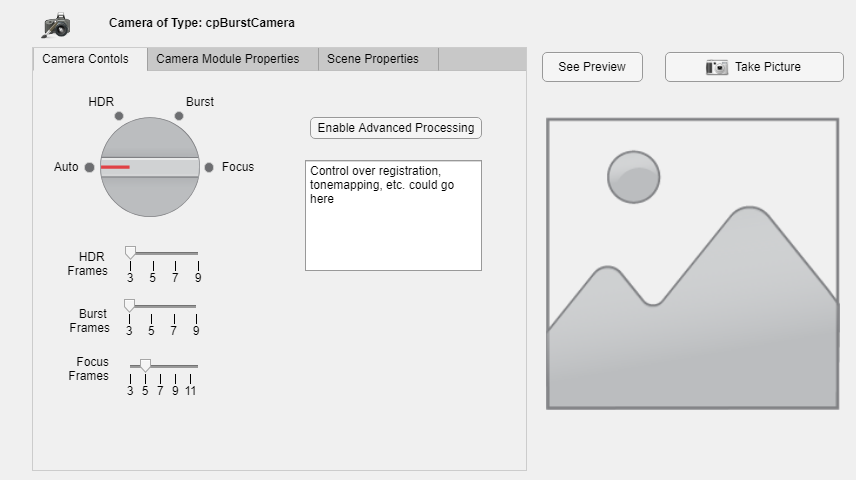

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures

burstImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst',...
    'insensorIP',false);

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.9 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
*** Rendering time for CornellBoxReference:  4.5 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.1 sec ***



Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.8 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
*** Rendering time for CornellBoxReference:  8.3 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.7 sec ***



*** Rendering time for CornellBoxReference:  8.3 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.7 sec ***



*** Rendering time for CornellBoxReference:  7.7 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.3 sec ***



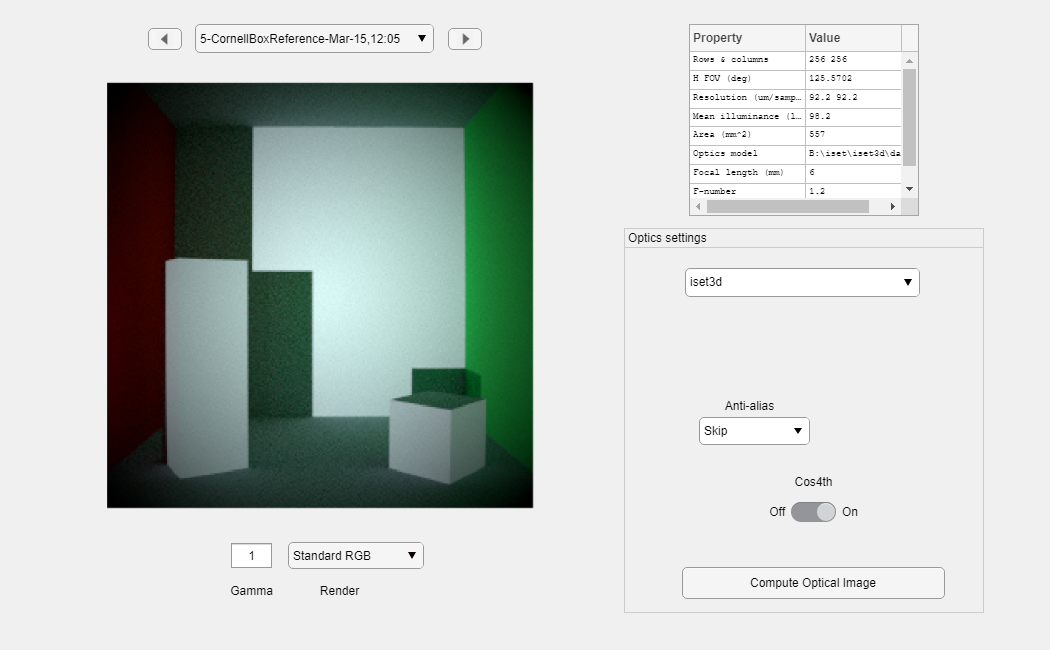

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.7 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
*** Rendering time for CornellBoxReference:  4.0 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.2 sec ***



Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file B:\iset\iset3d\local\CornellBoxReference\CornellBoxReference_depth.pbrt
Docker command
	docker run -ti --rm -w /CornellBoxReference -v B:/iset/iset3d/local/CornellBoxReference:/CornellBoxReference vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReference_depth.dat CornellBoxReference_depth.pbrt
*** Rendering time for CornellBoxReference_depth:  1.6 sec ***

  Reading image h=256 x w=256 x 31 spectral planes.
*** Rendering time for CornellBoxReference:  8.2 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.4 sec ***



*** Rendering time for CornellBoxReference:  7.3 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.5 sec ***



*** Rendering time for CornellBoxReference:  8.5 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.3 sec ***



*** Rendering time for CornellBoxReference:  8.7 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.6 sec ***



*** Rendering time for CornellBoxReference:  7.2 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.5 sec ***



*** Rendering time for CornellBoxReference:  7.4 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.3 sec ***



*** Rendering time for CornellBoxReference:  7.6 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.8 sec ***



*** Rendering time for CornellBoxReference:  7.5 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.4 sec ***



*** Rendering time for CornellBoxReference:  8.0 sec ***

Decoding lens parameters from lens file name B:\iset\iset3d\data\lens\dgauss.22deg.6.0mm.dat
*** Rendering time for CornellBoxReference_depth:  3.4 sec ***



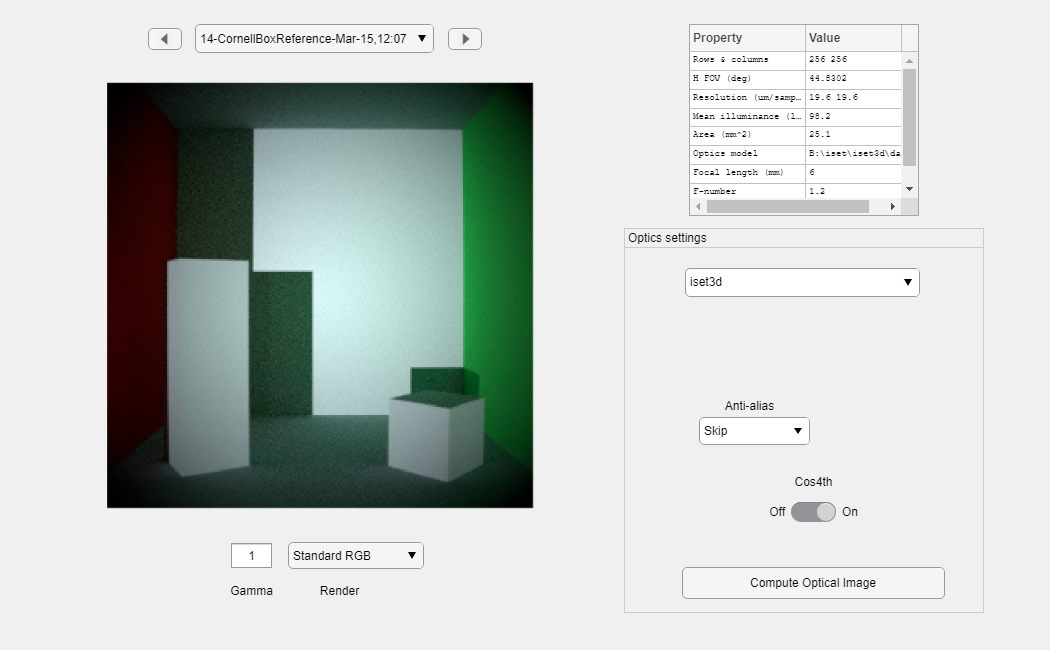

Fmeasure[100%]
SMeasure     

[100%]
Weights [100%]
Fusion [100%]

Elapsed time: 694.95 s:
Reading  (0.1%).
Fmeasure (99.9%).
SMeasure (0.0%).
Fusion   (0.0%).



stackedImage = ourCamera.TakePicture(pbrtCPScene, 'FocusStack',...
    'numFocusFrames', 9, 'imageName','Focus Stacked',...
    'insensorIP',false);

Burst vs. Stacked with no moion

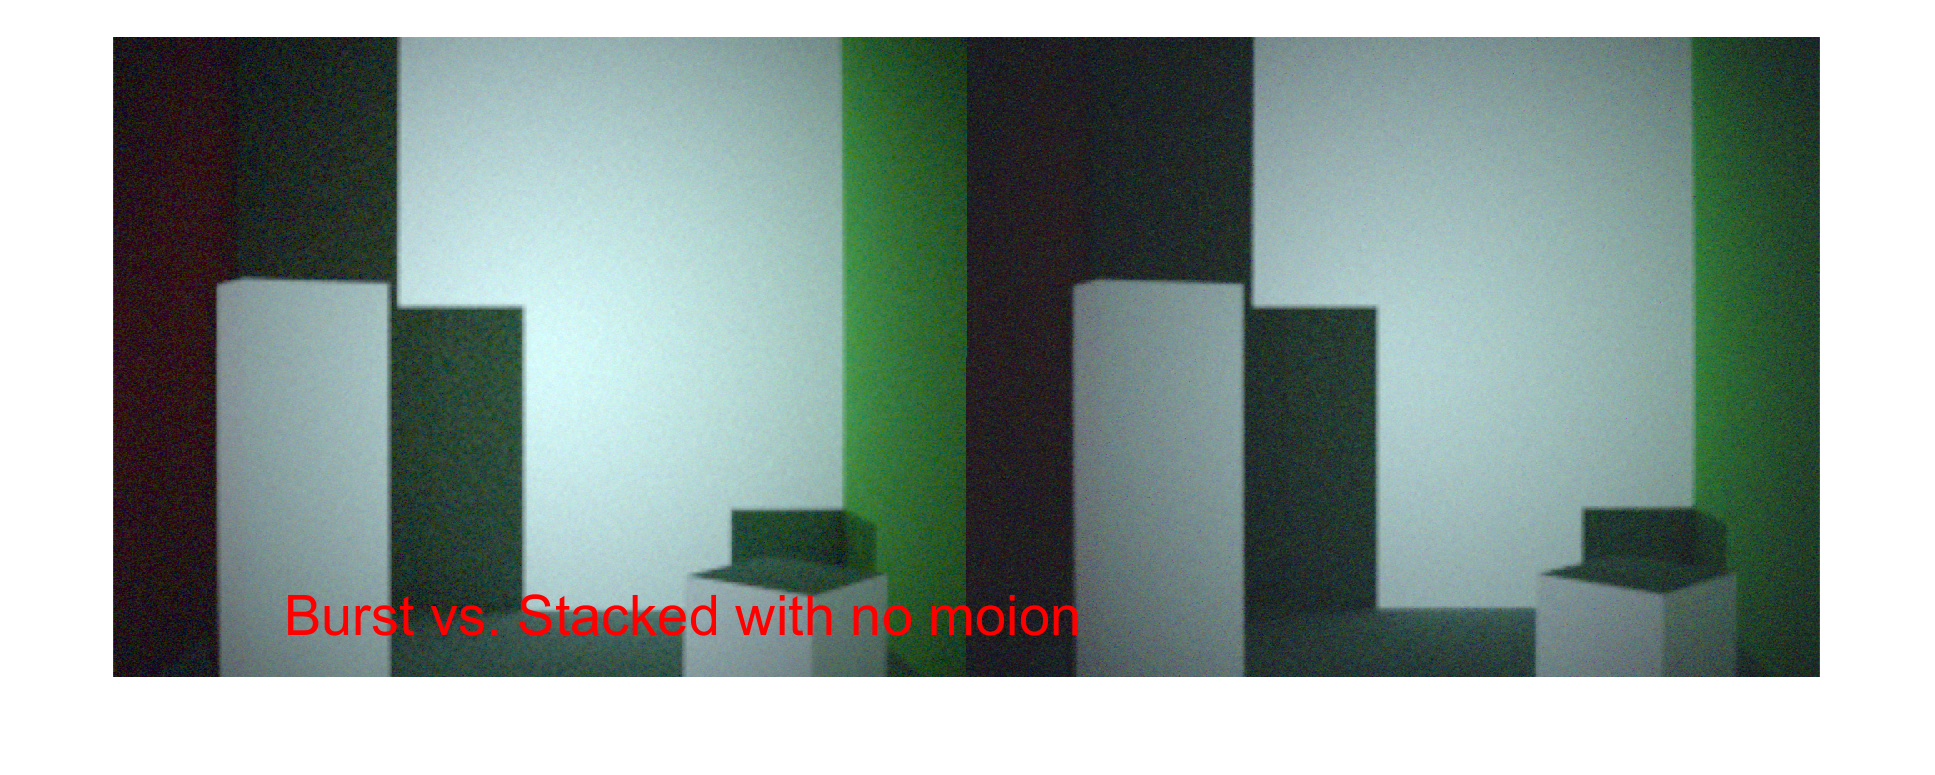


cpCompareImages(burstImage, stackedImage, 'Burst vs. Stacked with no moion');

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

cpCompare ran  on: NVIDIA Corporation GeForce RTX 3090/PCIe/SSE2with driver version: 4.6.0 NVIDIA 461.72


disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

cpCompare ran  in: 123.0156 seconds of CPU time.


disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));

cpCompare ran  in: 906.4669 total seconds.
